# **Introductory script illustrating aspects of the TreeShrew optics**

#### **See also**: 

*Copyright: Nicolas P. Cottaris,  ISETBio Team,, 2018*

# OUTLINE

 **   Step 1.** Generate ThreeShrew optics with default params

 **   Step 2.** Generate ThreeShrew optics with custom params

# **Step 1.** Generate TreeShrew optics with default params

### Initialize the default optics and plot some aspects

The default optics is based on a Gaussian Point Spead Function (PSF)  with a 20 micron sigma.

psfRangeArcMin = 50

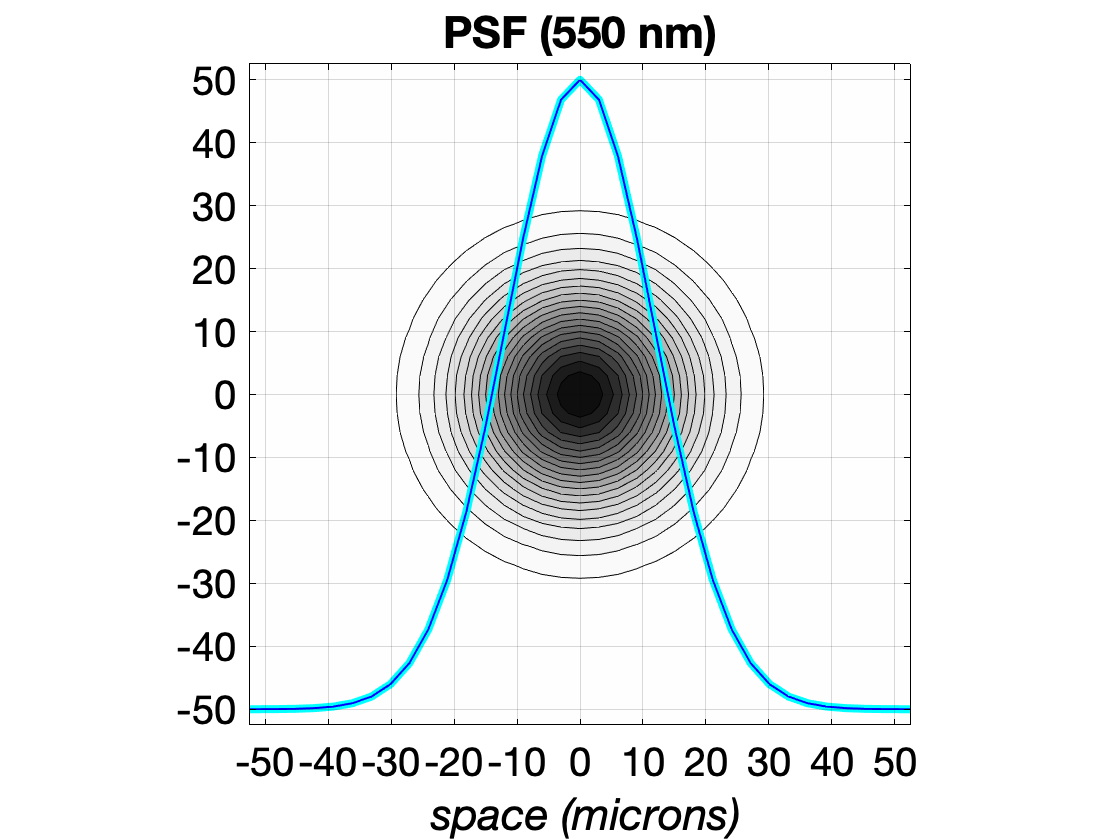

% Default tree shew optics
theOI = oiTreeShrewCreate();

% Visualize the PSF at 550 nm
visualizedSpatialSupportArcMin = 100;
visualizePSF(theOI, 550, visualizedSpatialSupportArcMin);

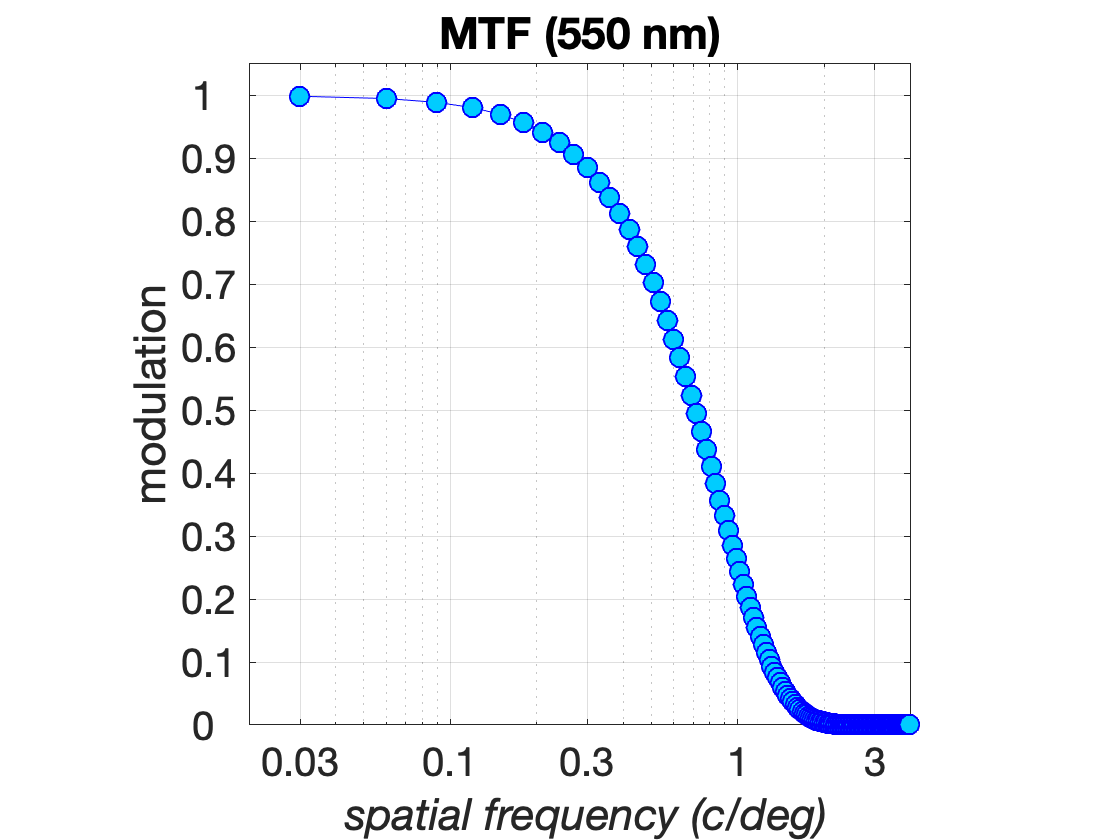


% Visualize the OTF at 550 nm
visualizedSpatialSfrequencyCPD = 4.0;
visualizeOTF(theOI, 550, visualizedSpatialSfrequencyCPD);

# **Step 2.** Generate custom TreeShrew optics

### Set a 40$\mu m$ sigma PSF

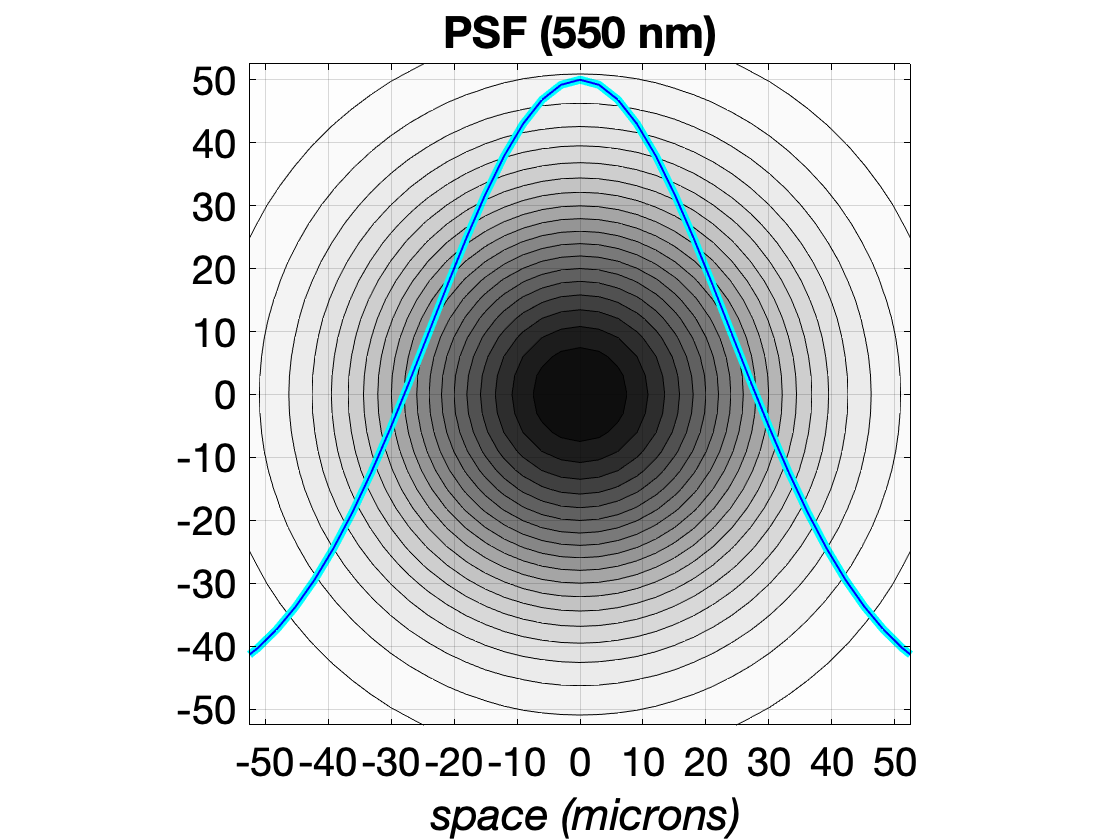

% Custom sigma tree shew optics 
theOI = oiTreeShrewCreate(...
    'inFocusPSFsigmaMicrons', 40 ... % 40 microns
);

% Visualize the PSF at 550 nm
visualizePSF(theOI, 550, visualizedSpatialSupportArcMin);

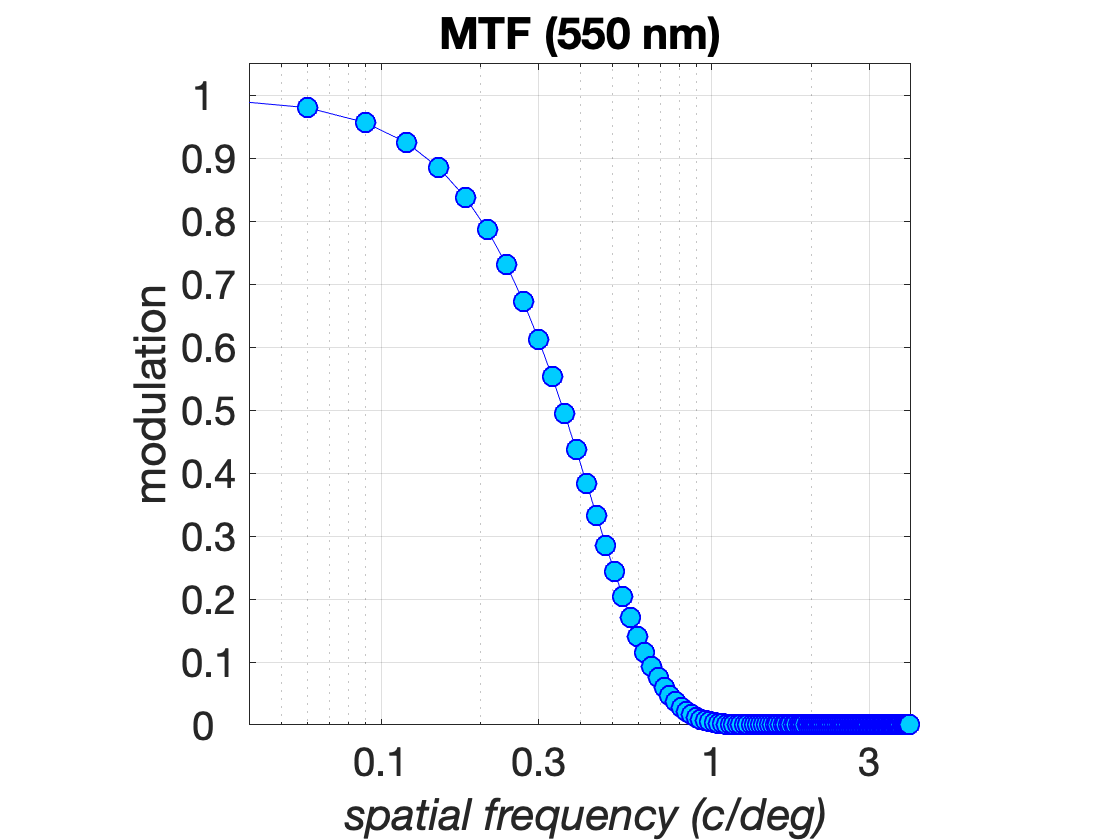



% Visualize the OTF at 550 nm
visualizeOTF(theOI, 550, visualizedSpatialSfrequencyCPD);

### Set a 10$\mu m$ sigma PSF. Also increase the spatial frequency support to 20 c/deg (default is 10 c/deg) to get a better spatial sampling

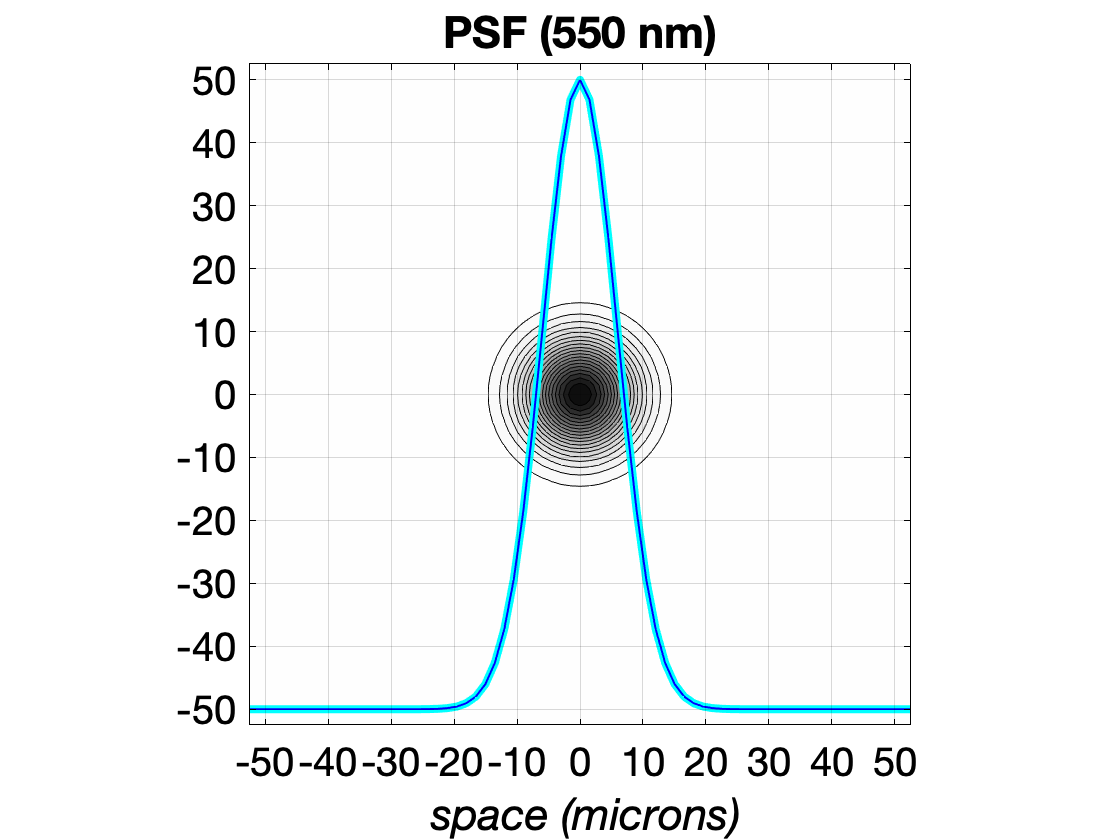

% Custom sigma tree shew optics
theOI = oiTreeShrewCreate(...
    'inFocusPSFsigmaMicrons', 10, ... % 10 microns
    'maxSF', 20 ...                   % increased SF support
);

% Visualize the PSF at 550 nm
visualizePSF(theOI, 550, visualizedSpatialSupportArcMin);

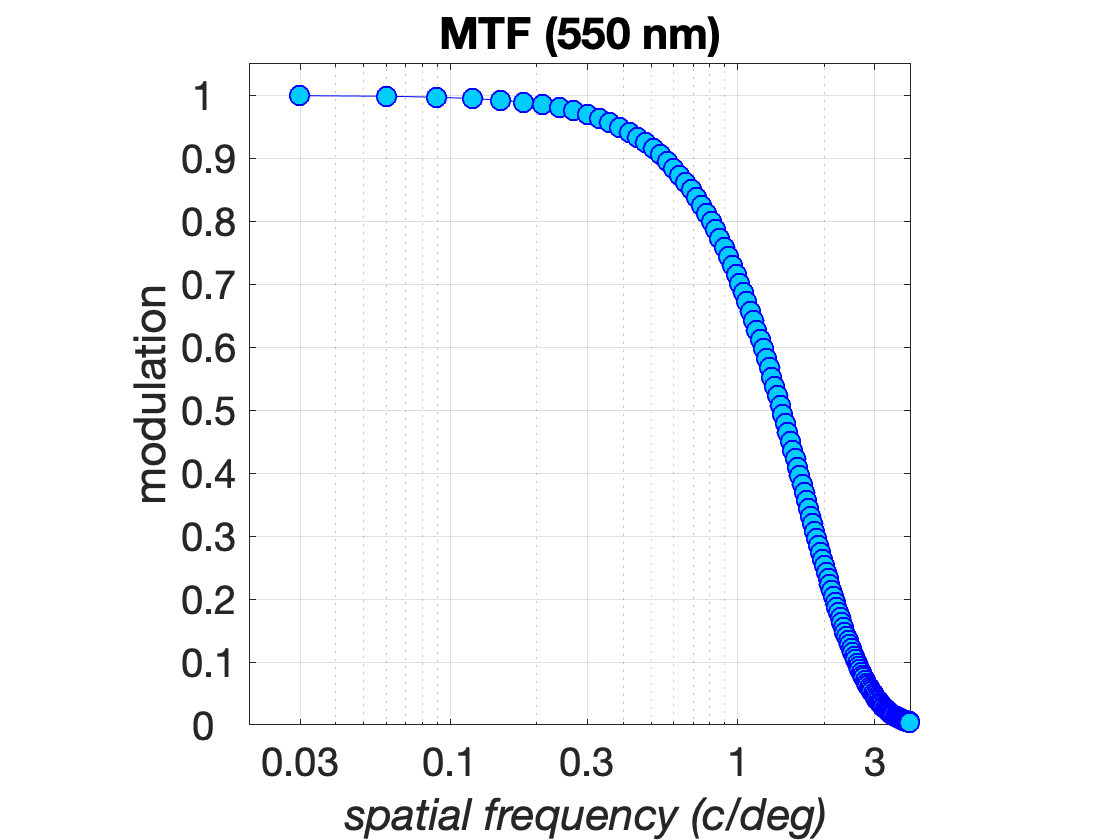


% Visualize the OTF at 550 nm
visualizeOTF(theOI, 550, visualizedSpatialSfrequencyCPD);